% define

numsim = 100000;    % number of simulations to run
samplesize = 50;    % number of data points in each sampe


% pre-aalocate the result vector

results = zeros(1,numsim);


% loop over simulations

for num=1:numsim
    
    % draw two sets of random numbers, each from the normal distribution
    
    data = randn(samplesize,2);
    
    % compute the correlation betweeen the two sets of numbers and store
    % the result
    
    results(num) = corr(data(:,1),data(:,2));
end

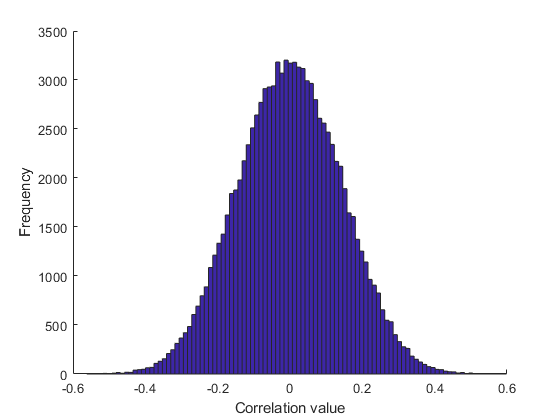

% visualize the results

figure; hold on;
hist(results, 100);

ax = axis;

mx = max(abs(ax(1:2)));  % make the x-axis simmetric around 0 

axis([-mx mx ax(3:4)]);

xlabel('Correlation value');
ylabel('Frequency');

% although the two sets of numbers were drawn from independent probability
% distributions ( and so should on average exhibit zero correlation), due
% to our limited sample size, we sometimes observer positive or negative
% correlation values. What is the value below which most correlation
% magnitudes lie? let's use 95% as the definition of "most".
val = prctile(abs(results),95);

val

val = 0.2784

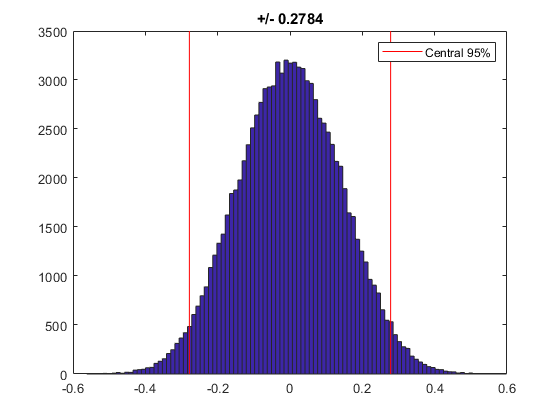

% visualize this on the figure
ax = axis;
hold on;

h0 = hist(results,100);
h1 = plot([val val], ax(3:4),'r-');
h2 = plot(-[val val], ax(3:4),'r-');

legend(h1, 'Central 95%');
title(sprintf('+/- %.4f',val));